%%%%%%%%%%%%%%%%% Forecasting accuracy analysis %%%%%%%%%%%%%%%%%
% StartDateF  = 33;
% HorizonValsF=[1, 4];
% dNForecast=zeros(Tdata,length(HorizonValsF));
% dDForecast=zeros(Tdata,length(HorizonValsF));
% dNActual=zeros(Tdata,length(HorizonValsF));
% dDActual=zeros(Tdata,length(HorizonValsF));
% 
% %--- Regress mobility on alpha to estimate the elasticity h ---%
% 
% for iH = 1:length(HorizonValsF)
%     HorizonF  = HorizonValsF(iH);
%     EndtDateF = Tdata+1-HorizonF;
%     
%     for iF = StartDateF:EndtDateF
%         GDP_F = GDP(1:iF-6);
%         referenceGDP_F = referenceGDP(1:iF-1);
%         
%         %--- Impute alpha (regress alpha on M)---%
%         Malt_F=M(1:iF-1);
%         alpha_F = (1 - GDP(1:iF-6)./referenceGDP(1:iF-6));   % output loss in percentage
%         X_F = Malt_F(iF-6-17:iF-6);
%         Y_F = alpha_F(iF-6-17:iF-6);
%         XC_F = [ones(length(X_F),1), X_F];
%         s_F = (XC_F'*XC_F)\XC_F'*Y_F;         % OLS estimate of h with constant
%         reg_F = XC_F*s_F;
%         r_F = Y_F - reg_F;
%         eps_p_F = zeros(iF-1-(iF-6),1);
%         eps_p_F(1) = r_F(end);
%         for i = 1:iF-1-(iF-6)-1
%             eps_p_F(i+1) = 1*eps_p_F(i);
%         end
%         alpha_pred_F = s_F(1)+s_F(2)*Malt_F((iF-6)+1:iF-1)+eps_p_F;
%         
%         alpha_F = [alpha_F;alpha_pred_F];
%         
%         %--- Regress mobility on alpha to estimate the elasticity h ---%
%         Y_F = M(4:iF-6);
%         X_F = alpha_F(4:iF-6);
%         if hconstant == 0
%             Y_F = Y_F - 1;
%             h_all_F = (X_F'*X_F)\X_F'*Y_F;              % OLS estimate of h
%             reg_F = X_F*h_all_F;
%             r_F = Y_F - reg_F;                % r is the residuals, which is the observed minus fitted values
%             SSE_F = sum(r_F.^2);            % SSE is the sum of squared errors
%             MSE_F=SSE_F/(length(Y_F)-1);      % mean squared error
%             h_all_se_F=sqrt(MSE_F/sum(X_F.^2));   % standard error of h
%         elseif hconstant == 1
%             XC_F = [ones(length(X_F),1), X_F];
%             h_all_F = (XC_F'*XC_F)\XC_F'*Y_F;         % OLS estimate of h with constant
%             reg_F = XC_F*h_all_F;
%             r_F = Y_F - reg_F;
%             SSE_F = sum(r_F.^2);
%         end
%         h_F = h_all_F;
%         
%         %--- Compute the history of S, I, R, D in the data period ---%
%         S_F = zeros(iF,1);
%         I_F = zeros(iF,1);
%         R_F = zeros(iF,1);
%         D_F = zeros(iF,1);
%         S_F(1)=POP0;
%         for i = 1:iF-1
%             S_F(i+1)=S_F(i)-N(i);
%             I_F(i+1)=I_F(i)+N(i)-gamma*I_F(i)-dD(i);
%             R_F(i+1)=R_F(i)+gamma*I_F(i);
%             D_F(i+1)=D_F(i)+dD(i);
%         end
%         
%         %--- Compute the history of time-varying parameters ---%
%         
%         delta_F = (D_F(2:iF)-D_F(1:iF-1))./I_F(1:iF-1);
%         beta_tilde_F = -POP0*((S_F(2:iF)-S_F(1:iF-1))./(S_F(1:iF-1).*I_F(1:iF-1)));   % overall infection rate
%         
%         if hconstant == 0
%             beta_F = beta_tilde_F./(1+h_all_F*alpha_F).^k;                                      % raw infection rate
%         elseif hconstant == 1
%             %     beta = beta_tilde./(h(1)+h(2)*alpha).^k;
%             beta_F = beta_tilde_F./(1+(h_all_F(2)/h_all_F(1))*alpha_F).^k;
%         end
%         
%         IV_F     = [S_F(iF),I_F(iF),R_F(iF),D_F(iF)];
%         alphaT_F = alpha(iF:iF+HorizonF-1); %Use actual values because we are interested in conditional forecasts.
%         beta_average_F = mean(beta_F(iF-RetroPeriod:iF-1));
%         delta_average_F = mean(delta_F(iF-1-RetroPeriod:iF-1));
%         betaT_F = beta_average_F*ones(HorizonF,1);
%         deltaT_F = delta_average_F*ones(HorizonF,1);
%         V_F = zeros(HorizonF,1);
%         gammaT_F=gamma*ones(HorizonF,1);
%         
%         [CumD_F,AverageAlpha_F,SimData_F,SimN_F]=Covid_projection(IV_F,alphaT_F,betaT_F,gammaT_F,deltaT_F,V_F,h_F,k,POP0,hconstant);
%         
%         dNForecast(iF,iH) = sum(SimN_F(1:HorizonF));
%         dDForecast(iF,iH) = CumD_F-IV_F(4);
%         dNActual(iF,iH)   = sum(N(iF:iF+HorizonF-1));
%         dDActual(iF,iH)   = D(iF+HorizonF-1)-D(iF-1);
%     end
% end

clear variables
load('/Users/Daisuke/Desktop/Dropbox/Research/fujii_nakata/Website/Forecast.mat')

CurrentD = load('/Users/Daisuke/Desktop/Dropbox/Research/fujii_nakata/Website/Codes/Japan20210208.mat');
Tdata = CurrentD.Tdata;
Month = CurrentD.Month;

figure_save = 1;

StartDateF  = 33;

format short
xtick1_F=StartDateF+4:8:Tdata;
xtick4_F=StartDateF+4:8:Tdata;
fs_F=10;
fs_legend_F=10;
fs_title=12;
for l = 1:2
     if l == 1
            figure(10)
        elseif l == 2
            figure(101)
     end
subplot(2,2,1)
plot(StartDateF:(Tdata),dNForecast(StartDateF:Tdata,1),'r',StartDateF:(Tdata),dNActual(StartDateF:Tdata,1),'k','LineWidth',1.5)
if l == 1
title({'Conditional Forecast vs. Actual';'(New cases)'},'FontSize',fs_title,'FontWeight','normal')
elseif l == 2
    title({'予測と実現値';'(新規感染者数)'},'FontSize',fs_title,'FontWeight','normal')
end
xlim([StartDateF (Tdata)])
xticks(xtick1_F)
xticklabels(Month(xtick1_F))
ax = gca;
ax.YAxis.Exponent = 0;
ax.YAxis.FontSize = fs_F;
ax.XAxis.FontSize = fs_F;
ytickformat('%,6.0f')
legend('Forecast','Actual','FontSize',fs_legend_F,'Location','Northwest')
subplot(2,2,2)
plot(StartDateF:(Tdata),dDForecast(StartDateF:Tdata,1),'r',StartDateF:(Tdata),dDActual(StartDateF:Tdata,1),'k','LineWidth',1.5)
if l == 1
title({'Conditional Forecast vs. Actual';'(New deaths)'},'FontSize',fs_title,'FontWeight','normal')
elseif l == 2
    title({'予測と実現値';'(新規死亡者数)'},'FontSize',fs_title,'FontWeight','normal')
end
ax = gca;
ax.YAxis.FontSize = fs_F;
ax.XAxis.FontSize = fs_F;
ax.YAxis.Exponent = 0;
ytickformat('%,6.0f')
xlim([StartDateF (Tdata)])
xticks(xtick1_F)
xticklabels(Month(xtick1_F))
legend('Forecast','Actual','FontSize',fs_legend_F,'Location','Northwest')
subplot(2,2,3)
plot(StartDateF:(Tdata),dNForecast(StartDateF:Tdata,1)-dNActual(StartDateF:Tdata,1),'k','LineWidth',1.5)
if l == 1
title({'Conditional Forecast Errors',' (New cases)'},'FontSize',fs_title,'FontWeight','normal')
elseif l == 2
    title({'予測誤差',' (新規感染者数)'},'FontSize',fs_title,'FontWeight','normal')
end
xlim([StartDateF (Tdata)])
xticks(xtick1_F)
xticklabels(Month(xtick1_F))
yline(0)
ax = gca;
ax.YAxis.FontSize = fs_F;
ax.XAxis.FontSize = fs_F;
ax.YAxis.Exponent = 0;
ytickformat('%,6.0f')
subplot(2,2,4)
plot(StartDateF:(Tdata),dDForecast(StartDateF:Tdata,1)-dDActual(StartDateF:Tdata,1),'k','LineWidth',1.5)
if l == 1
title({'Conditional Forecast Errors',' (New deaths)'},'FontSize',fs_title,'FontWeight','normal')
elseif l == 2
    title({'予測誤差',' (新規死亡者数)'},'FontSize',fs_title,'FontWeight','normal')
end
xlim([StartDateF (Tdata)])
xticks(xtick1_F)
xticklabels(Month(xtick1_F))
yline(0)
ax = gca;
ax.YAxis.FontSize = fs_F;
ax.XAxis.FontSize = fs_F;
ax.YAxis.Exponent = 0;
ytickformat('%,6.0f')
end

ans =   ConstantLine with properties:

    InterceptAxis: 'y'
            Value: 0
            Color: [0.1500 0.1500 0.1500]
        LineStyle: '-'
        LineWidth: 0.5000
            Label: ''
      DisplayName: ''

  Show all properties


ans =   ConstantLine with properties:

    InterceptAxis: 'y'
            Value: 0
            Color: [0.1500 0.1500 0.1500]
        LineStyle: '-'
        LineWidth: 0.5000
            Label: ''
      DisplayName: ''

  Show all properties


ans =   ConstantLine with properties:

    InterceptAxis: 'y'
            Value: 0
            Color: [0.1500 0.1500 0.1500]
        LineStyle: '-'
        LineWidth: 0.5000
            Label: ''
      DisplayName: ''

  Show all properties


ans =   ConstantLine with properties:

    InterceptAxis: 'y'
            Value: 0
            Color: [0.1500 0.1500 0.1500]
        LineStyle: '-'
        LineWidth: 0.5000
            Label: ''
      DisplayName: ''

  Show all properties


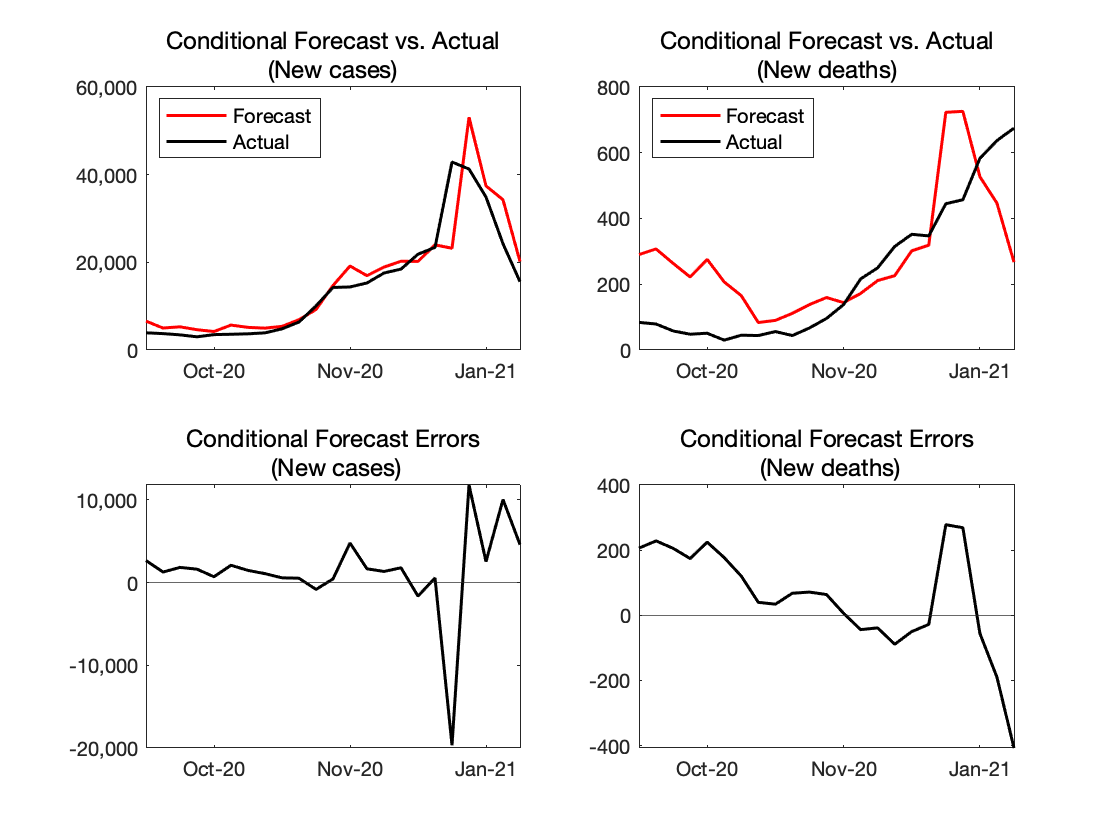

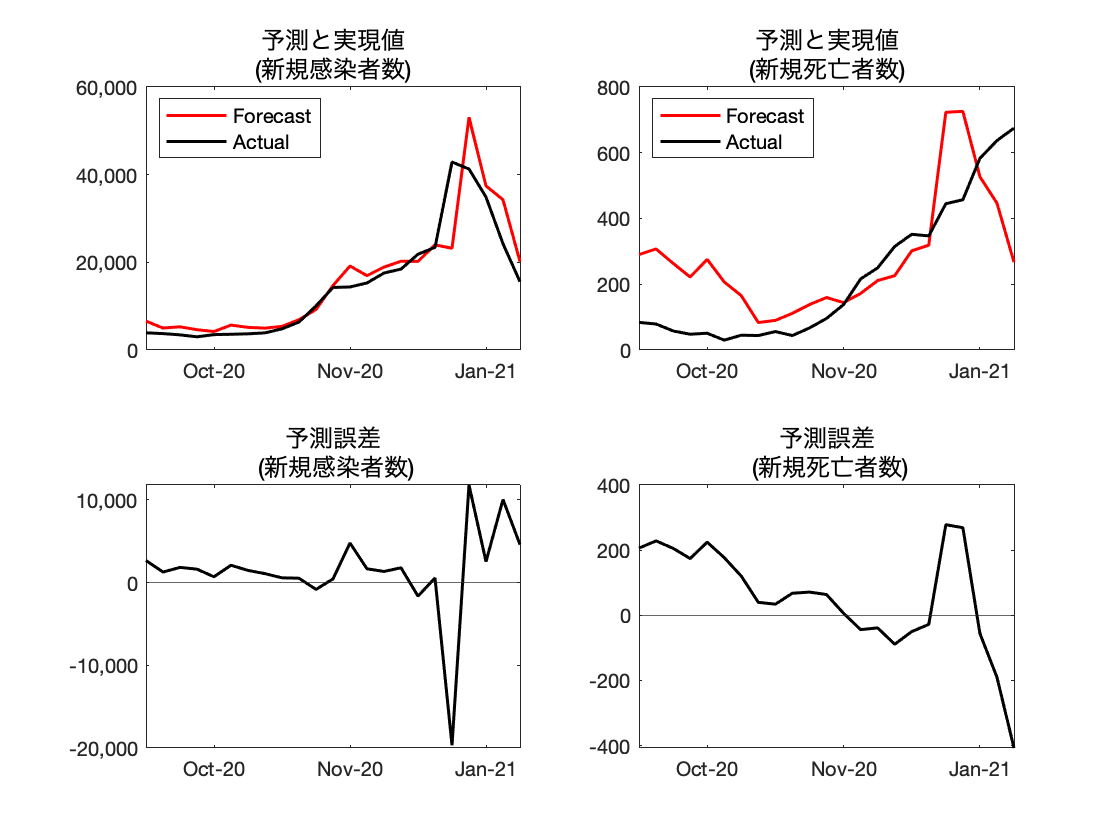


if figure_save == 1
    saveas(figure(10),'/Users/Daisuke/Desktop/Dropbox/Research/fujii_nakata/Website/Codes/Figures/ForecastErrors.png');
    saveas(figure(101),'/Users/Daisuke/Desktop/Dropbox/Research/fujii_nakata/Website/Codes/Figures/ForecastErrors_jp.png');
end